clear
% rng(0);
load arith_64;
% add_mat=[0 1; 1 0];

clc

cnt11=0;
p=6;
q=2^p;
nH = 20;
nL = 20;
nc = 20;

EbN0_dB =-2

EbN0_dB = -2

%3; % SNR per bit in dB
EbN0 = 10^(EbN0_dB/10); % Linear SNR
sigm = sqrt(1/(2*EbN0)); % Noise standard deviationq = 64;

words = (0:q-1);
alph_bin =  fliplr(dec2bin(words, p) - 48);
alph_bin_mod = (-1).^alph_bin;



d2hst = zeros(nH, nL);
d3hst = d2hst;
d2hst1 = zeros(1,q );
h0 = 50;
while cnt11<50000
    cnt11 = cnt11 + 1;


%     y_bin1 = randi([0 1], 1, p);
%     y_bin1 = zeros(1,p);
%     y_bin1_m = 1-2*y_bin1;
    a0_dec = randi([0 q-1], 1, 1);
    b0_dec = randi([0 q-1], 1, 1);

    a_dec = add_mat(a0_dec+1, b0_dec+1);
    b_dec = mul_mat(a_dec+1, h0+1);
    y_bin1 = de2bi(a_dec, p);
    y_bin1_m1 = 1-2*y_bin1;
    y_bin2 = de2bi(b_dec, p);
    y_bin2_m2 = 1-2*y_bin2;

    nse1 = sigm*randn(size(y_bin1_m1));
    y_bin_nse1 = y_bin1_m1 + nse1;
    nse2 = sigm*randn(size(y_bin2_m2));
    y_bin_nse2 = y_bin2_m2 + nse2;

    a1 = -LLR_simple3(y_bin_nse1,sigm, alph_bin);
    [a, aa]=sort(a1, 'ascend');
    aa = aa-1;

    b1 = -LLR_simple3(y_bin_nse2,sigm, alph_bin);
    [b, bb0]=sort(b1, 'ascend');
    bb0 = bb0-1;
    bb = div_mat(bb0+1,h0+1);
    
    d2hst1(bb(1)+1) = d2hst1(bb(1)+1) + 1;

    a = a(1:nL);
    a_gf = aa(1:nL);
    b = b(1:nH);
    b_gf = bb(1:nH);
    c=nan(nH, nL);
    cc=c;
    

    for i = 1 : nH
        for j=1:nL
            cc(i,j)=add_mat(1+aa(i),1+bb(j));
            c(i,j) = a(i)+b(j);
        end
    end
    
    u1_gf = 0*ones(q,1);    
    u1 = inf(q,1);
    Sij = -ones(q,2);
    for i=1:nH
        for j=1:nL
            if  u1(cc(i,j)+1)>c(i,j)
                Sij(cc(i,j)+1,:)=[i, j];
                u1(cc(i,j)+1)=c(i,j);
                u1_gf(cc(i,j)+1)=1;
            end
        end
    end
    [bj1,j11]=mink(u1, nc);
    tmp1 = d2hst(1,2);
    for i=1:nc
        d2hst(Sij(j11(i),1), Sij(j11(i),2))=d2hst(Sij(j11(i),1), Sij(j11(i),2))+1;
    end

    i1 = find(a_gf==a_dec);
    j1 = find(b_gf==b_dec);

    d3hst(i1, j1) = d3hst(i1, j1)+1;

end

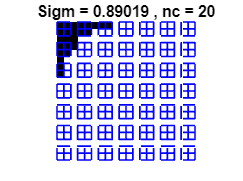

[sortedValues, linearIndices] = maxk(d2hst(:), nc+4);
[rowIndices, colIndices] = ind2sub(size(d2hst), linearIndices);

bubbleregion = zeros(nH, nL);
bubbleregion(sub2ind(size(d2hst), rowIndices, colIndices)) = 1;  % Set top N values to black

figure;
imagesc(bubbleregion);  % Show as an image
colormap([1 1 1; 0 0 0]);  % White (0) and Black (1)
axis equal off;  % Remove axis for a cleaner look
title("Top N Values Highlighted");

% Add grid lines
hold on;
for i = 0:nH
    % Draw horizontal grid lines
    plot([0, nL] + 0.5, [i, i] + 0.5, 'b--', 'LineWidth', 1);
    % Draw vertical grid lines
    plot([i, i] + 0.5, [0, nH] + 0.5, 'b--', 'LineWidth', 1);
end
hold off;
title(['Sigm = ' num2str(sigm) ' , nc = ' num2str(nc)])



table.ADDGF = add_mat;
% output_LLR = F_EMS(a1, b1, 0, table, q, 20, bubbleregion, 1e5, 0);